# 小さなデータから順位表を作る(2)

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear; clc; close all;

csvファイルをtable形式で読み込む

tbl=readtable('../data/smallDataExample.csv');

チーム名の文字列を抽出する

teamNameStrs=unique([tbl.TeamAName;tbl.TeamBName]);

それぞれのチーム名の列をカテゴリ型の変数に変換する

tbl.TeamAName=categorical(tbl.TeamAName, teamNameStrs);
tbl.TeamBName=categorical(tbl.TeamBName, teamNameStrs);

tblの内容を画面に表示する

tbl

tbl = 60×5 table
    Date    TeamAName    TeamBName    TeamAScore    TeamBScore
    ____    _________    _________    __________    __________

      1         A            B             5             5    
      2         C            D             1             7    
      3         E            A            11             0    
      4         F            C             3             1    
      5         F            B            10             3    
      6         D            E             5             0    
      7         C            B             1             3    
      8         D            A            12             5    
      9         E            C             2             1    
     10         A            F             2            10    
     11         B            E             5             8    
     12         D            F             5             2    
     13         F            E             5             4    
     14         C            A       

引き分けの試合数を確認する

sum(tbl.TeamAScore==tbl.TeamBScore)

ans = 7

勝，引分，負試合数，および得失点を集計する

集計用の変数を準備する

Wins=zeros(size(teamNameStrs));
Draws=zeros(size(teamNameStrs));
Loses=zeros(size(teamNameStrs));
ScoresFor=zeros(size(teamNameStrs));
ScoresAgainst=zeros(size(teamNameStrs));

for n1=1:size(tbl,1)

それぞれの試合で両チームが何番に対応するかを見つける

    TeamANum=find(teamNameStrs==tbl.TeamAName(n1));
    TeamBNum=find(teamNameStrs==tbl.TeamBName(n1));    

各チームの得失点を加える

    ScoresFor(TeamANum)=ScoresFor(TeamANum)+tbl.TeamAScore(n1);
    ScoresFor(TeamBNum)=ScoresFor(TeamBNum)+tbl.TeamBScore(n1);
    ScoresAgainst(TeamANum)=ScoresAgainst(TeamANum)+tbl.TeamBScore(n1);
    ScoresAgainst(TeamBNum)=ScoresAgainst(TeamBNum)+tbl.TeamAScore(n1);

得点の大小で場合分けし，勝・引分・負それぞれに加える

    if tbl.TeamAScore(n1)>tbl.TeamBScore(n1)
        Wins(TeamANum)=Wins(TeamANum)+1;
        Loses(TeamBNum)=Loses(TeamBNum)+1;
    elseif tbl.TeamAScore(n1)==tbl.TeamBScore(n1)
        Draws(TeamANum)=Draws(TeamANum)+1;
        Draws(TeamBNum)=Draws(TeamBNum)+1;
    elseif tbl.TeamAScore(n1)<tbl.TeamBScore(n1)
        Loses(TeamANum)=Loses(TeamANum)+1;
        Wins(TeamBNum)=Wins(TeamBNum)+1;
    end
end

チーム名，および勝・引分・負それぞれの回数を列とするtableを作る(表の作成，表への変数の追加)

tbl_teams=table(teamNameStrs,'VariableNames',{'Team'});
tbl_teams.Team=categorical(tbl_teams.Team);
tbl_teams=addvars(tbl_teams, Wins, Draws, Loses, ScoresFor, ScoresAgainst);

勝率，得点割合の列を追加する

WinRatio=Wins./(Wins+Loses);
ScoreRatio=ScoresFor./(ScoresFor+ScoresAgainst)

ScoreRatio =     0.1603
    0.5793
    0.4912
    0.6981
    0.6278
    0.5795


tbl_teams=addvars(tbl_teams, WinRatio, ScoreRatio);

勝率が高い順にソートする

tbl_teams=sortrows(tbl_teams,"WinRatio","descend");

tbl_teamsの内容を画面に表示する

tbl_teams

tbl_teams = 6×8 table
    Team    Wins    Draws    Loses    ScoresFor    ScoresAgainst    WinRatio    ScoreRatio
    ____    ____    _____    _____    _________    _____________    ________    __________

     D       12       4        4         111             48            0.75      0.69811  
     F       12       1        7         102             74         0.63158      0.57955  
     E       10       3        7         113             67         0.58824      0.62778  
     B        9       2        9          95             69             0.5      0.57927  
     C        7       3       10          56             58         0.41176      0.49123  
     A        3       1       16          38            199         0.15789      0.16034  


積み上げ(stacked)帯グラフを作る

figure;
barh([tbl_teams.Wins tbl_teams.Draws, tbl_teams.Loses], ...
    'stacked');

格子(grid)を追加する

grid on;

現在のグラフ(軸．gca=get current axis)の設定を変更する

set(gca,'fontname','メイリオ');
set(gca,'ydir','reverse');

y軸方向の値のtickとその文字列を設定する

yticks(1:size(tbl_teams,1));
yticklabels(string(tbl_teams.Team));

各軸の説明(label)を設定する

xlabel('試合数');
ylabel('チーム');

凡例(legend)を設定する

legend({'勝','引分','負'},'location','northoutside', ...
    'Orientation',"horizontal")

図をpdf形式で出力する

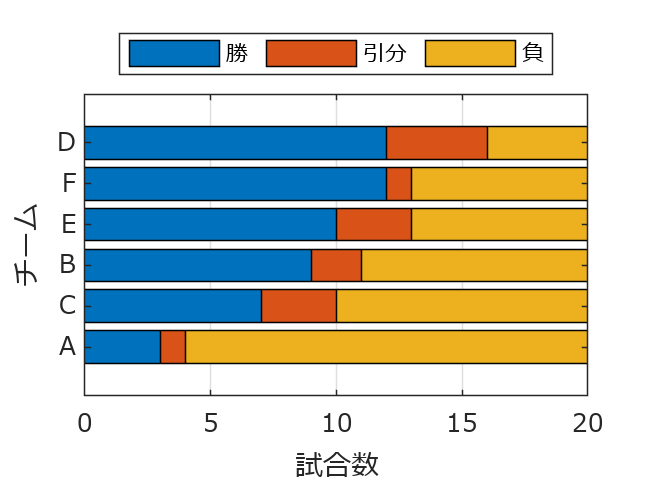

exportgraphics(gcf, 'fig_simpleDataExample01.pdf');

新しい図を作る

figure

横軸：得点割合，縦軸：勝率とした散布図

scatter(tbl_teams.ScoreRatio, tbl_teams.WinRatio,'.');
grid on;
axis([0 1 0 1])
set(gca,'fontname','メイリオ');

各軸の説明(label)を設定する

xlabel('得点割合');
ylabel('勝率');

チーム名を散布図内に書く

text(tbl_teams.ScoreRatio, tbl_teams.WinRatio, tbl_teams.Team, ...
    'fontname','メイリオ','horizontalalignment','left');

図をpdf形式で出力する

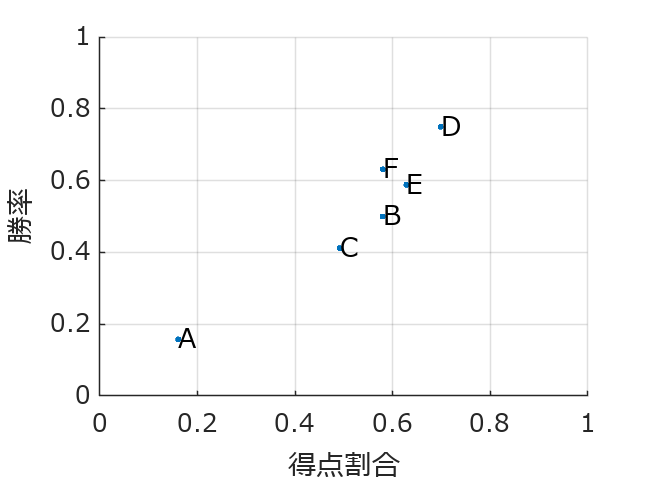

exportgraphics(gcf, 'fig_simpleDataExample02.pdf');